# 675.752: ADACS

# Example Simulation from the Textbook

# Sect. 7.5.2: Control Laws Compared

This simulates the response of a spacecraft to commanded Euler angles using Euler-angle driven PD control. It follows the example in section 7.5.2 of the course textbook.

Sidi, M., "Spacecraft Dynamics & Control," Cambridge University Press, 2006.

Assumes:

- principal axes

- small commanded angles

- unrestricted control torques

© 2021 Johns Hopkins University

Version 1.0, Uday J. Shankar. (uday.shankar@jhuapl.edu)

## Simulation parameters

% start and stop time
sim.start_time = 0.0; % {sec}
sim.end_time = 25.0;  % {sec}

% simulation time step
sim.time_step = 0.1;  % {sec}

## Spacecraft Parameters

(Specified in the text, p. 157)

% Inertias
sc.Ix = 1000; % {kg-m^2}
sc.Iy = 500;  % {kg-m^2}
sc.Iz = 700;  % {kg-m^2}

% Control gains
sc.wn   = 1.0; % b-w {rad/s}
sc.zeta = 1.0; % {1}
% ... X axis
sc.Kx  = 1000; % {N-m/rad}
sc.Kdx = 2000; % {N-m-s/rad}
% ... Y axis
sc.Ky  = 500;  % {N-m/rad}
sc.Kdy = 1000; % {N-m-s/rad}
% ... Z axis
sc.Kz  = 700;  % {N-m/rad}
sc.Kdz = 1400; % {N-m-s/rad}

% Control start time
sc.control_start_time = 1.0; % {sec}

% Initial values
sc.X0 = zeros(7,1); % iniital state -- all zeros

## Commanded states

(Specified in the text, p.157)

% First set of initial conditions: small angles
cmd.phi   = deg2rad( 4); % {rad}
cmd.theta = deg2rad(-4); % {rad}
cmd.psi   = deg2rad(-6);  % {rad}

% get the DCM of the commanded state ([A_T])
cmd.DCM = angle2dcm(cmd.psi, cmd.theta, cmd.phi,'ZYX');

## Set up differential equation solver (ode45)

% ode45 options: use default values for tolerances
odeopts = odeset('RelTol',1E-8, 'AbsTol',1e-10, "OutputFcn",[]);

% simulation time span
t_span = sim.start_time : sim.time_step : sim.end_time;

% initial conditions
X0 = sc.X0;

## Run the simulation for the small angle case

Use the parameter version of derivative function (see Matlab help on ode45), so we can pass sc and cmd structs to the solver. 

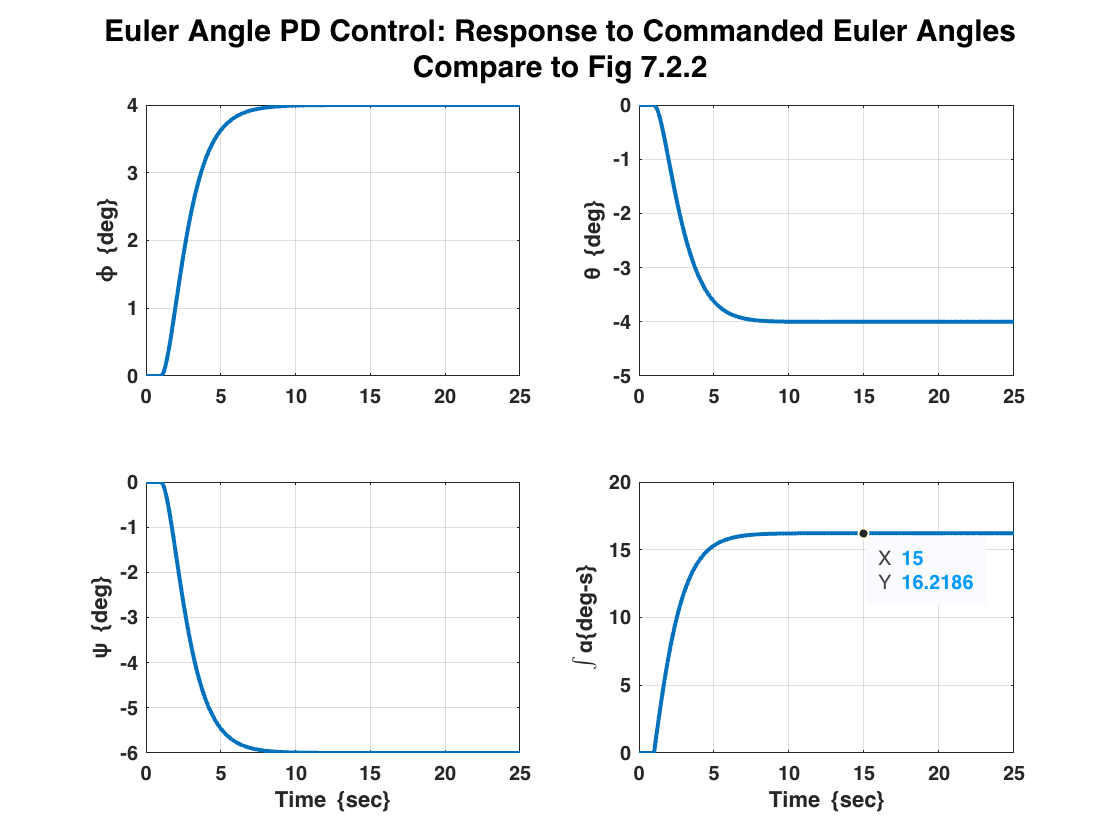

% ... derivative set for small angle case
dxdt = @(t,X) state_deriv(t, X, sc, cmd);

% Run simulation using ode45
[T,y1_rad] = ode45(dxdt, t_span, X0, odeopts);

% convert the output to deg, deg/s, and deg-s
y1 = rad2deg(y1_rad); %

% ======== Plot the results  =====================
figure("Name","Euler Angle Control Example (7.2.5)")
% ... Phi
subplot(221);
plot(T, y1(:,1),"LineWidth",2);
grid on; box on;
ylabel("\phi \{deg\}");
set(gca,'fontweight','bold');
xlim([0,25]);
% ... Theta
subplot(222);
plot(T, y1(:,2),"LineWidth",2);
grid on; box on;
ylabel("\theta \{deg\}");
set(gca,'fontweight','bold');
xlim([0,25]);
% ... Psi
subplot(223);
plot(T, y1(:,3),"LineWidth",2);
grid on; box on;
ylabel("\psi \{deg\}");
xlabel("Time \{sec\}");
set(gca,'fontweight','bold');
xlim([0,25]);
% .. Euler-int
subplot(224);
plot(T,y1(:,7),'LineWidth',2);
grid on; box on;
ylabel("\int\alpha\{deg-s\}");
xlabel('Time \{sec\}')
set(gca,'fontweight','bold');
xlim([0,25]);
% ... Add an overall title
sgtitle(["Euler Angle PD Control: Response to Commanded Euler Angles","Compare to Fig 7.2.2"],'fontweight','bold');
% Add a datatip showing value of EULERINT at 15 sec. (151 data point)
subplot(2,2,4)
ax = gca;
chart = ax.Children(1);
datatip(chart,'dataindex',151,'Location','southeast');

## Function to calculate Euler rates


$$\dot{\phi} = p + [q \sin\phi + r \cos\phi] \tan\theta \\
\dot{\theta} = q \cos\phi - r\sin\phi \\
\dot{\psi} = [q \sin\phi + r\cos\phi]\sec\theta$$
   
$$X=\left\lbrack \begin{array}{c}
\phi \\
\theta \\
\psi \\
p\\
q\\
r
\end{array}\right\rbrack$$


function [phi_dot, theta_dot, psi_dot] = euler_rates( X )

    % Parse the state
    phi   = X(1);
    theta = X(2);
    %psi   = X(3);

    % rates
    p = X(4);
    q = X(5);
    r = X(6);
    
    % calculate the Euler rates
    sin_phi = sin(phi);
    cos_phi = cos(phi);

    % phi_dot
    phi_dot = p + ( q*sin_phi + r*cos_phi ) * tan(theta); % Note: will raise error if theta = 90 deg.
    % theta_dot 
    theta_dot = q*cos_phi - r*sin_phi;
    % psi_dot
    psi_dot = (q*sin_phi + r*cos_phi) * sec(theta); % Note: will raise error if theta = 90 deg.
    
    % return to caller

end % function euler_rates

## Function to calculate controls

Controls are based on Euler angles and rates (assumes small angles)


$$X=\left\lbrack \begin{array}{c}
\phi \\
\theta \\
\psi \\
p\\
q\\
r
\end{array}\right\rbrack$$
 
$$\dot{\phi} = p + [q \sin\phi + r \cos\phi] \tan\theta \\
\dot{\theta} = q \cos\phi - r\sin\phi \\
\dot{\psi} = [q \sin\phi + r\cos\phi]\sec\theta$$


Controls are from Eq. 7.2.2, p. 153 of the text (note error in sign of second term in text)


$$T_{cx}=K_x(\phi_{com}-\phi)-K_{xd}\dot{\phi} \\
T_{cy}=K_y(\theta_{com}-\theta)-K_{yd}\dot{\theta} \\
T_{cz}=K_z(\psi_{com}-\psi)-K_{zd}\dot{\psi}$$


function [Tcx, Tcy, Tcz] = controls(t, X, sc, cmd)
    
    % Parse the state
    phi   = X(1);
    theta = X(2);
    psi   = X(3);
    
    % Get Euler rates
    [phi_dot, theta_dot, psi_dot] = euler_rates( X );
    
    % Control starts at sc.control_start_time
    if( t >= sc.control_start_time-eps) 
        % ... Calculate Tcx
        Tcx = sc.Kx *(cmd.phi   - phi) - sc.Kdx * phi_dot;
        % ... Calculate Tcy
        Tcy = sc.Ky *(cmd.theta - theta) - sc.Kdy * theta_dot;
        % ... Calculate Tcz
        Tcz = sc.Kz *(cmd.psi   - psi) - sc.Kdz * psi_dot;
    else
        Tcx = 0;
        Tcy = 0;
        Tcz = 0;
    end % if t >=  start time
    


end

## Function to calculate state derivatives


$$X=\left\lbrack \begin{array}{c}
\phi \\
\theta \\
\psi \\
p\\
q\\
r
\end{array}\right\rbrack$$
  
$$U=\left\lbrack \begin{array}{c}
u_x \\
u_y \\
u_z 
\end{array}\right\rbrack$$
  
$$Y=\left\lbrack \begin{array}{c}
\phi_d \\
\theta_d \\
\psi_d 
\end{array}\right\rbrack$$


Using 3-2-1 Euler transformation for Euler angles


$$I \dot{\omega}+\omega\times I\omega = T_c$$


Ref eq. 4.7.6, p.103 of the textbook for Euler rates


$$\dot{\phi} = p + [q \sin\phi + r \cos\phi] \tan\theta \\
\dot{\theta} = q \cos\phi - r\sin\phi \\
\dot{\psi} = [q \sin\phi + r\cos\phi]\sec\theta$$


For EULERINT, refer to sect. 7.2.2 for the defintion of the DCM error matrix, and equation A.4.6 of Appendix A for the definition of  the Euler-axis angle, $\alpha$


$$[A_E] = [A_S][A_T]^T$$



$$\cos\alpha = \frac{1}{2}\left( tr([A_E]) -1 \right)$$


function dX = state_deriv(t, X, sc, cmd)
    
    % Get Euler rates
    [phi_dot, theta_dot, psi_dot] = euler_rates( X );

    %% === Calculate controls ===
    [Tcx, Tcy, Tcz] = controls(t, X, sc, cmd);
    
    %% === Calculate the derivatives ===
    dX = zeros(7,1);
    
    % Angles
    dX(1) = phi_dot;
    dX(2) = theta_dot;
    dX(3) = psi_dot;
    
    % Calculate the omega X (I omega) term
    I = diag([sc.Ix, sc.Iy, sc.Iz]);
    w = X(4:6);
    w_x_Iw = cross(w, I*w);
    
    % Rates
    dX(4) = (Tcx - w_x_Iw(1)) / sc.Ix; 
    dX(5) = (Tcy - w_x_Iw(2)) / sc.Iy; 
    dX(6) = (Tcz - w_x_Iw(3)) / sc.Iz; 
    
    % Euler-int: integral of Euler-axis angle error
    phi = X(1);
    theta = X(2);
    psi = X(3);
    % DCM of the state ([A_S])
    DCM = angle2dcm(psi, theta, phi);
    % DCM Error
    DCM_e = DCM * cmd.DCM'; % [As][At]'
    % DCM diagonal terms
    %A11 = cos(theta)*cos(psi);
    %A22 = cos(phi)*cos(psi) + sin(theta)*sin(phi)*sin(psi);
    %A33 = cos(phi)*cos(theta);
    %Tr_A = A11 + A22 + A33;
    % Trace of DCM
    Tr_A = trace(DCM_e);
    % alpha = Euler-axis angle
    alpha = acos((Tr_A - 1.)/2.);
    % derivative of integral-alpha
    if( t >= sc.control_start_time )
        dX(7) = alpha;
    end
    

end